%validating our analytical solution with numerical solution available in
%https://rotations.berkeley.edu/a-tumbling-t-handle-in-space/
clear;
load analyticalsoln.mat
load numericalsoln.mat

I1,I2,I3,w1_0, w2_0, w3_0

I1 = 0.4000

I2 = 0.3000

I3 = 0.2000

w1_0 = 0.5000

w2_0 = 15

w3_0 = 0.5000

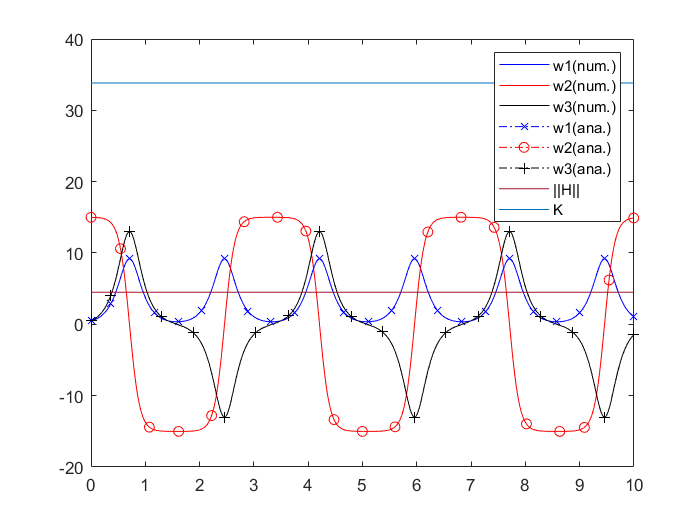

plot(t([1:2000],:), omega1([1:2000],:), 'b');
hold on;
plot(t([1:2000],:), omega2([1:2000],:), 'r');
plot(t([1:2000],:), omega3([1:2000],:), 'k');
fplot(w1, [0 t(2000,1)], '-.xb');
fplot(w2, [0 t(2000,1)], '-.or');
fplot(w3, [0 t(2000,1)], '-.+k');
fplot(H_, [0 t(2000,1)]);
fplot(K_, [0 t(2000,1)]);
legend('w1(num.)','w2(num.)','w3(num.)', 'w1(ana.)', 'w2(ana.)', 'w3(ana.)', '||H||', 'K');
hold off;